# TASK 1

#### Load

clear
close all
load('s31.mat')

#### Save important data

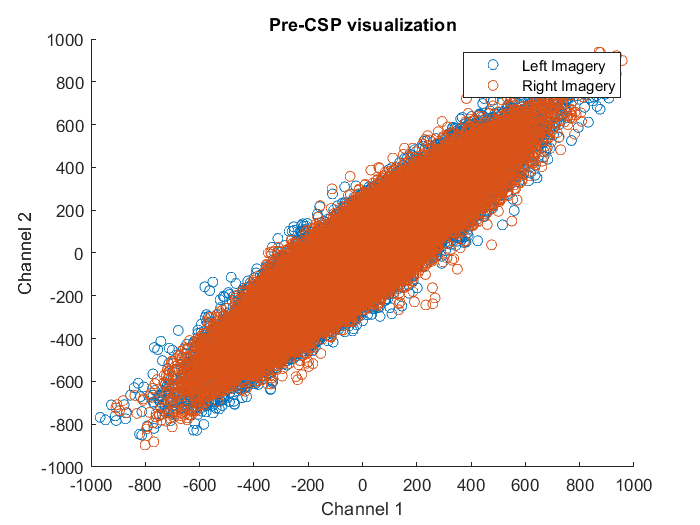

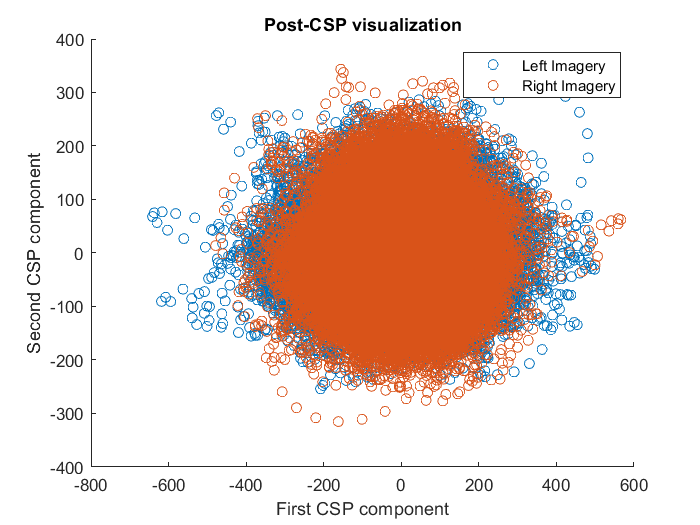

ans = 0.0513

ans = -0.0513

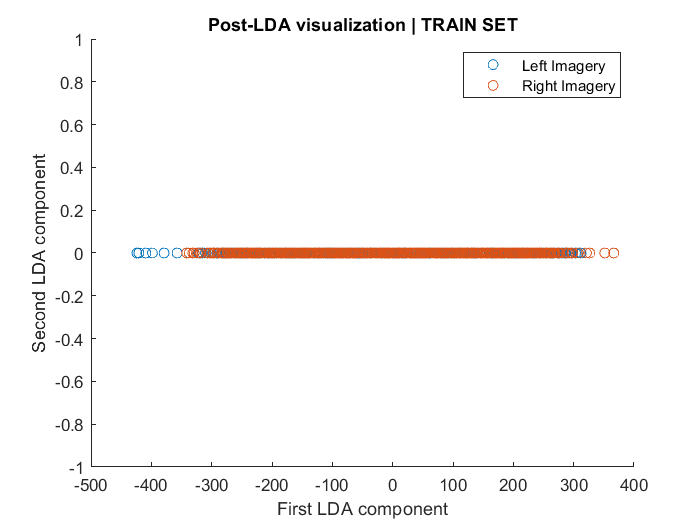

train_accuracy = 0.4625

train_accuracy_right = 0.4500

train_accuracy_left = 0.4750

test_accuracy = 0.5500

test_accuracy_right = 0.4500

test_accuracy_left = 0.6500

Fs=eeg.srate;

n_trials=eeg.n_imagery_trials;
left_imagery=eeg.imagery_left(1:64,:)';
right_imagery=eeg.imagery_right(1:64,:)';
imagery_event_indices=find(eeg.imagery_event~=0);
n_channels=64;
active_phase_length=3*Fs;
n_samples=size(left_imagery,1);
n_samples_per_epoch=3*Fs;

#### Filtering

fl=7; fh=40; %Beta waves and u waves 
left_imagery_detrend=detrend(left_imagery);
right_imagery_detrend=detrend(right_imagery);


filtered_left_imagery=filter(betau_filter,left_imagery);
filtered_right_imagery=filter(betau_filter,right_imagery);

filtered_left_imagery_active=zeros((3*Fs)*n_trials,n_channels);
filtered_right_imagery_active=zeros((3*Fs)*n_trials,n_channels);
for i=1:n_trials
filtered_left_imagery_active(1+(i-1)*3*Fs:i*3*Fs,:)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+active_phase_length-1,1:n_channels);
filtered_right_imagery_active(1+(i-1)*3*Fs:i*3*Fs,:)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+active_phase_length-1,1:n_channels);
end

[f,esd_filtered_left_imagery_active]=data_spectrum_corr(filtered_left_imagery_active',Fs,'e',0);
[f,esd_filtered_right_imagery_active]=data_spectrum_corr(filtered_right_imagery_active',Fs,'e',0);

#### Epoching


left_dataset=zeros(active_phase_length,n_channels,n_trials);
right_dataset=zeros(active_phase_length,n_channels,n_trials);
dataset=struct('data',cell(1,2*n_trials),'label',cell(1,2*n_trials));

for i=1:n_trials
left_dataset(:,:,i)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+active_phase_length-1,1:n_channels);
right_dataset(:,:,i)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+active_phase_length-1,1:n_channels);

dataset(2*i-1).data=left_dataset(:,:,i);
dataset(2*i-1).label='l';

dataset(2*i).data=right_dataset(:,:,i);
dataset(2*i).label='r';
end

dataset_random=dataset(randperm(length(dataset)));

# STESSA COSA MA CON SAMPLES TRATTATI COME FEATURES

## training and test set

percentage=0.95;
n_train=round(n_trials*percentage);
n_test=n_trials-n_train;

%left_dataset_random=left_dataset(:,:,randperm(size(left_dataset,3)));
%right_dataset_random=right_dataset(:,:,randperm(size(right_dataset,3)));

left_dataset_random=left_dataset;
right_dataset_random=right_dataset;

train_left=left_dataset_random(:,:,1:n_train);
train_right=right_dataset_random(:,:,1:n_train);

test_left=left_dataset_random(:,:,n_train+1:end);
test_right=right_dataset_random(:,:,n_train+1:end);

## CSP

concatenated_train_left=zeros(size(train_left,[1,2]));
concatenated_train_right=zeros(size(train_right,[1,2]));

for i=1:n_train
    concatenated_train_left(1+(i-1)*n_samples_per_epoch:i*n_samples_per_epoch,:)=train_left(:,:,i);
    concatenated_train_right(1+(i-1)*n_samples_per_epoch:i*n_samples_per_epoch,:)=train_right(:,:,i);
end

C_left=cov(concatenated_train_left);
C_right=cov(concatenated_train_right);

M_CSP=C_right^-1*C_left;

[eigVectors_CSP,eigValues_CSP]=eig(M_CSP);
eigValues_CSP=diag(eigValues_CSP);
[eigValues_CSP,indices_CSP]=sort(eigValues_CSP,'descend');
Lmax=eigValues_CSP(1); Lmin=eigValues_CSP(end);
Emax_CSP=eigVectors_CSP(:,indices_CSP(1));Emin_CSP=eigVectors_CSP(:,indices_CSP(end));

transformation_matrix=[Emax_CSP Emin_CSP]; %n_channels x 2

%Transformation: n_samples x n_channels * n_channels x 2 -> n_samples x 2

VISUALIZATION


figure;
scatter(concatenated_train_left(:,1),concatenated_train_left(:,2))
hold on
scatter(concatenated_train_right(:,1),concatenated_train_right(:,2))
legend('Left Imagery','Right Imagery')
xlabel('Channel 1')
ylabel('Channel 2')
title('Pre-CSP visualization')
hold off

transformed_concatenated_train_left=concatenated_train_left*transformation_matrix;
transformed_concatenated_train_right=concatenated_train_right*transformation_matrix;

figure;
scatter(transformed_concatenated_train_left(:,1),transformed_concatenated_train_left(:,2))
hold on
scatter(transformed_concatenated_train_right(:,1),transformed_concatenated_train_right(:,2))
legend('Left Imagery','Right Imagery')
xlabel('First CSP component')
ylabel('Second CSP component')
title('Post-CSP visualization')

## LDA

transformed_concatenated_train_left=zeros(n_train,2*n_samples_per_epoch);
transformed_concatenated_train_right=zeros(n_train,2*n_samples_per_epoch);

for i=1:n_train
    transformed_concatenated_train_left(i,:)=reshape(left_dataset_random(:,:,i)*transformation_matrix,1,[]);
    transformed_concatenated_train_right(i,:)=reshape(right_dataset_random(:,:,i)*transformation_matrix,1,[]);    
end

mean_left=mean(transformed_concatenated_train_left,1);
m_right=mean(transformed_concatenated_train_right,1);

SW=cov(transformed_concatenated_train_right)+cov(transformed_concatenated_train_left);

mean_global=mean([mean_left;m_right],1);

SB=n_train*((mean_left-mean_global)'*(mean_left-mean_global)+(m_right-mean_global)'*(m_right-mean_global));


[eigVectors_LDA,eigValues_LDA]=eig(SW^-1*SB);
eigValues_LDA=diag(eigValues_LDA);
[eigValues_LDA,indices_LDA]=sort(eigValues_LDA,'descend');

Emax_LDA=eigVectors_LDA(:,indices_LDA(1));

T=eigVectors_LDA(:,indices_LDA(1));

b=-0.5*Emax_LDA'*(mean_left+m_right)';

TRAIN ACCURACY

close all

classification_results_train_left=(Emax_LDA'*transformed_concatenated_train_left'+b)
classification_results_train_right=(Emax_LDA'*transformed_concatenated_train_right'+b)

accuracy_train_left=sum(classification_results_train_left<0)/n_train
accuracy_train_right=sum(classification_results_train_right>0)/n_train
accuracy_train=(accuracy_train_right+accuracy_train_left)/2

LDA_transformed_concatenated_train_right=(T'*transformed_concatenated_train_right')'+b;
LDA_transformed_concatenated_train_left=(T'*transformed_concatenated_train_left')'+b;

% figure;
% scatter(LDA_transformed_concatenated_test_left(:,1),LDA_transformed_concatenated_test_left(:,2))
% hold on
% scatter(LDA_transformed_concatenated_test_right(:,1),LDA_transformed_concatenated_test_right(:,2))
% legend('Left Imagery','Right Imagery')
% xlabel('First LDA component')
% ylabel('Second LDA component')
% title('Post-LDA visualization')


figure;
scatter(LDA_transformed_concatenated_train_left,zeros(size(LDA_transformed_concatenated_train_left)))
hold on
scatter(LDA_transformed_concatenated_train_right,zeros(size(LDA_transformed_concatenated_train_right)))
plot([0 0],[-1 1],'--')
hold off
legend('Left Imagery','Right Imagery')
xlabel('First LDA component')
ylabel('Second LDA component')
title('Post-LDA visualization | TRAIN SET')

NEGATIVE VALUE LEFT | POSITIVE VALUE RIGHT

TEST ACCURACY

close all
test_accuracy_left=0;
test_accuracy_right=0;

transformed_concatenated_test_left=zeros(n_test,2*n_samples_per_epoch);
transformed_concatenated_test_right=zeros(n_test,2*n_samples_per_epoch);

for i=1:n_test
    transformed_concatenated_test_left(i,:)=reshape(left_dataset_random(:,:,n_train+i)*transformation_matrix,1,[]);
    transformed_concatenated_test_right(i,:)=reshape(right_dataset_random(:,:,n_train+i)*transformation_matrix,1,[]);    
end

classification_results_test_left=(Emax_LDA'*transformed_concatenated_test_left'+b)
classification_results_test_right=(Emax_LDA'*transformed_concatenated_test_right'+b)

test_accuracy_right=sum(classification_results_test_right>0)/n_test
test_accuracy_left=sum(classification_results_test_left<0)/n_test
test_accuracy=(test_accuracy_right+test_accuracy_left)/(2)

LDA_transformed_concatenated_test_right=(T'*transformed_concatenated_test_right')'+b;
LDA_transformed_concatenated_test_left=(T'*transformed_concatenated_test_left')'+b;

figure;
scatter(LDA_transformed_concatenated_test_left,zeros(size(LDA_transformed_concatenated_test_left)))
hold on
scatter(LDA_transformed_concatenated_test_right,zeros(size(LDA_transformed_concatenated_test_right)))
plot([0 0],[-1 1],'--')
hold off
legend('Left Imagery','Right Imagery')
xlabel('First LDA component')
ylabel('Second LDA component')
title('Post-LDA visualization | TEST SET')

#### Cose da fare

Aggiungere plot tratteggiato nella prima soluzione

Mettere scatter plot test set